# **Actividad 2: Robot planar**

**Paola Rojas Domínguez** **A01737136**

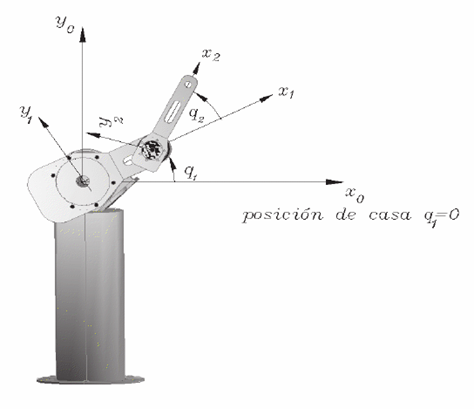

clear all
close all
clc

%Variables simbólicas
syms th1(t) l1 t th2(t) l2 th3(t) l3
RP = [0 0 0];
Q = [th1 th2 th3];
disp('Coordenadas articulares'); Q

Coordenadas articulares


$$Q(t) = \left(\begin{array}{ccc} {\mathrm{th}}_{1}\left(t\right) & {\mathrm{th}}_{2}\left(t\right) & {\mathrm{th}}_{3}\left(t\right) \end{array}\right)$$

Qp = diff(Q, t);
disp('Velocidades articulares'); Qp %Vector de las velocidades de las particulaciones

Velocidades articulares


$$Qp(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right) \end{array}\right)$$

GDL = size(RP, 2);
GDL_str = num2str(GDL);
%Cinemática Directa
%Articulación 1
%Posición de la junta 1 respecto a 0
P(:,:,1) = [l1*cos(th1);
            l1*sin(th1); 
            0];

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1) = [cos(th1) -sin(th1) 0;
            sin(th1)  cos(th1) 0;
            0         0        1];
%Articulación 2
%Posición de la junta 1 respecto a 0
P(:,:,2) = [l2*cos(th2);
            l2*sin(th2); 
            0]; 

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0;
            0         0        1];

%Articulación 3
%Posición de la junta 1 respecto a 0
P(:,:,3) = [l3*cos(th3);
            l3*sin(th3); 
            0]; 

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,3) = [cos(th3) -sin(th3) 0;
            sin(th3)  cos(th3) 0;
            0         0        1];
%Creamos un vector de ceros
Vector_Zeros = zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL) = P(:,:,GDL); %****

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL) = R(:,:,GDL); %****
for i = 1:GDL
    i_str = num2str(i);
    %Locales
    disp(strcat('Robot Planar: A', i_str));
    A(:,:,i) =  simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    A(:,:,i)
    disp('    ');
    %Globales
    try
        T(:,:,i) = T(:,:,i-1) * A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Robot Planar: T', i_str));
    T(:,:,i) = simplify(T(:,:,i));
    T(:,:,i)
    disp('    ');

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    %disp(strcat('Matriz de Rotación de la matriz global T', i_str));
    %RO(:,:,i)
    %disp('    ');
    %disp(strcat('Vector de traslación de la matriz global T', i_str));
    %PO(:,:,i)
    %disp('    ');
end

Robot Planar: A1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Planar: T1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Planar: A2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Planar: T2


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & \sigma_{2}\,l_{2}+\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1}\\ \sigma_{1} & \sigma_{2} & 0 & \sigma_{1}\,l_{2}+\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

Robot Planar: A3


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Planar: T3


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & \sigma_{2}\,l_{3}+\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}+\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1}\\ \sigma_{1} & \sigma_{2} & 0 & \sigma_{1}\,l_{3}+\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}+\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

%Cálculo del jacobiano lineal de forma diferencial
%Derivadas parciales de x
Jv11 = functionalDerivative(PO(1,1,GDL), th1);
Jv12 = functionalDerivative(PO(1,1,GDL), th2);
Jv13 = functionalDerivative(PO(1,1,GDL), th3);

%Derivadas parciales de y
Jv21 = functionalDerivative(PO(2,1,GDL), th1);
Jv22 = functionalDerivative(PO(2,1,GDL), th2);
Jv23 = functionalDerivative(PO(2,1,GDL), th3);

%Derivadas parciales de z
Jv31 = functionalDerivative(PO(3,1,GDL), th1);
Jv32 = functionalDerivative(PO(3,1,GDL), th2);
Jv33 = functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d = simplify([Jv11 Jv12 Jv13;
                 Jv21 Jv22 Jv23;
                 Jv31 Jv32 Jv33]);
%disp('Jacobiano lineal obtenido de forma diferencial'); jv_d
%Cálculo del jacobiano lineal y angular de forma analítica
%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);
for k = 1:GDL
    if(RP(k)==0) %Casos de articulación rotacional
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k) = [0,0,1];
        end

    elseif(RP(k)==1) %Casos de articulación prismática
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1];
        end
        Jw_a(:,k) = [0,0,0];
    end
end

%Despliegue
Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); Jv_a

Jacobiano lineal obtenido de forma analítica


$$Jv\_a = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\sigma_{3}\right)\,l_{3}-\sigma_{1}-\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1} & -\sin\left(\sigma_{3}\right)\,l_{3}-\sigma_{1} & -l_{3}\,\sin\left(\sigma_{3}\right)\\ \cos\left(\sigma_{3}\right)\,l_{3}+\sigma_{2}+\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1} & \cos\left(\sigma_{3}\right)\,l_{3}+\sigma_{2} & l_{3}\,\cos\left(\sigma_{3}\right)\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}\\ \sigma_{3}={\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

disp('Jacobiano angular obtenido de forma analítica'); Jw_a

Jacobiano angular obtenido de forma analítica


$$Jw\_a = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

%Velocidades Lineales y Angulares
V = simplify(Jv_a*Qp');
disp('Robot Planar: Velocidad lineal'); V

Robot Planar: Velocidad lineal


$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\sigma_{4}\,\left(\sin\left(\sigma_{1}\right)\,l_{3}+\sin\left(\sigma_{2}\right)\,l_{2}\right)-\sigma_{5}\,\left(\sin\left(\sigma_{1}\right)\,l_{3}+\sin\left(\sigma_{2}\right)\,l_{2}+\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1}\right)-l_{3}\,\sigma_{3}\,\sin\left(\sigma_{1}\right)\\ \sigma_{4}\,\left(\cos\left(\sigma_{1}\right)\,l_{3}+\cos\left(\sigma_{2}\right)\,l_{2}\right)+\sigma_{5}\,\left(\cos\left(\sigma_{1}\right)\,l_{3}+\cos\left(\sigma_{2}\right)\,l_{2}+\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{1}\right)+l_{3}\,\sigma_{3}\,\cos\left(\sigma_{1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\\ \sigma_{2}={\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{4}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{5}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}$$

W = simplify(Jw_a*Qp');
disp('Robot Planar: Velocidad angular'); W

Robot Planar: Velocidad angular


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)} \end{array}\right)$$